% Load the images
data = load('../data/assignmentImageDenoising_phantom.mat');
noiseless = data.imageNoiseless;
noisy = data.imageNoisy;

[rows,cols] = size(noisy);

noisy = noisy/max(noisy(:));
noiseless = noiseless/max(noiseless(:));

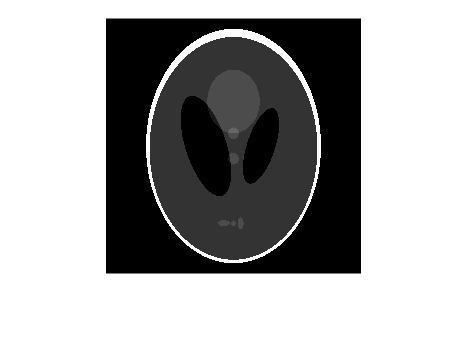

imshow(noiseless);

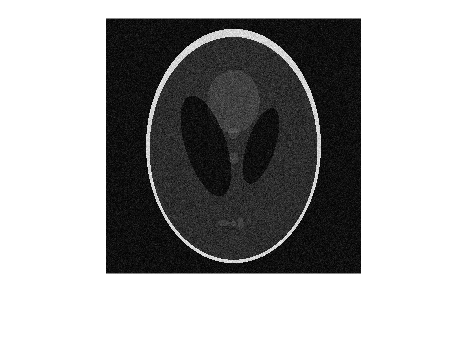

imshow(noisy);

est = noisy;

ll = -0.5 * sum((Y(:) - X(:)).^2);